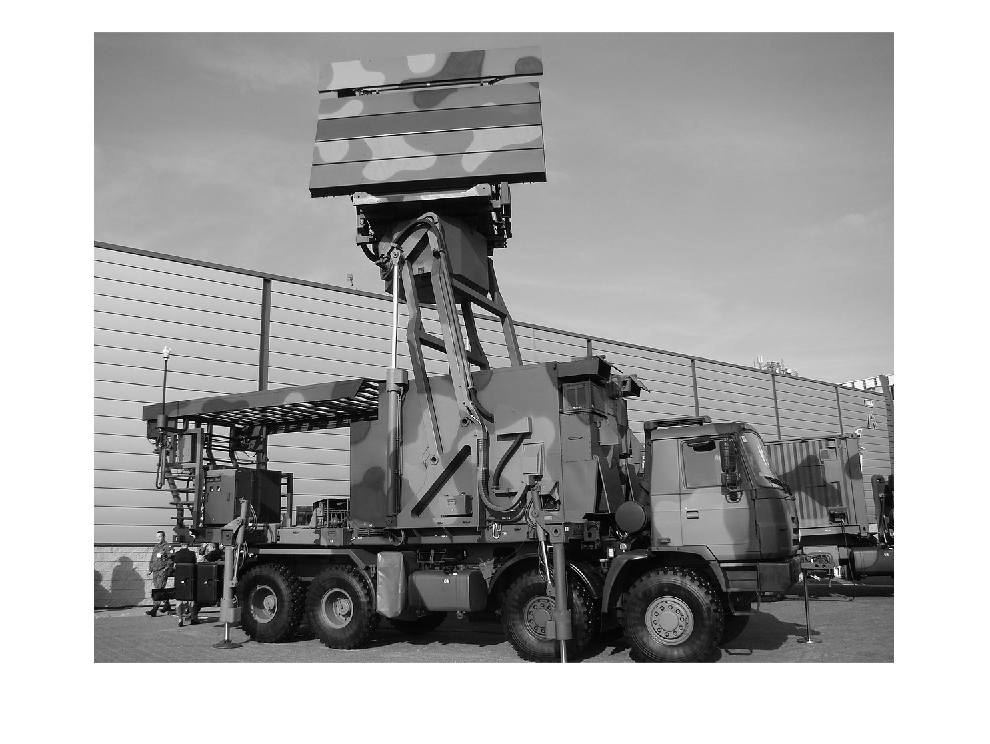

%Script to recognize radars

clc
clear

%Obraz źródłowy
image = imread('nur15.jpg');
% image = imresize(image, 0.2);
% image = imrotate(image, -90); %Obót obrazu o 90*, jeśli potrzeba
%Wyświetlenie obrazu
image = RGBToGray(image); %zamiana na obraz monochromatyczny
imshow(image); 

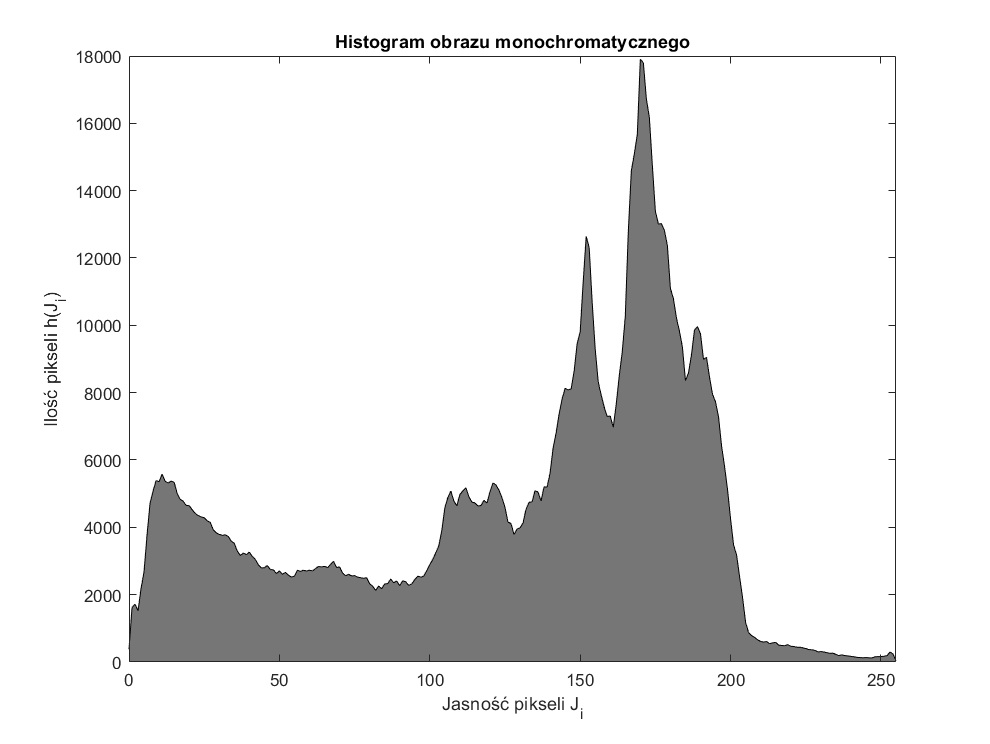


%Wyświetlenie histogramu
showhistogram(image, -1);

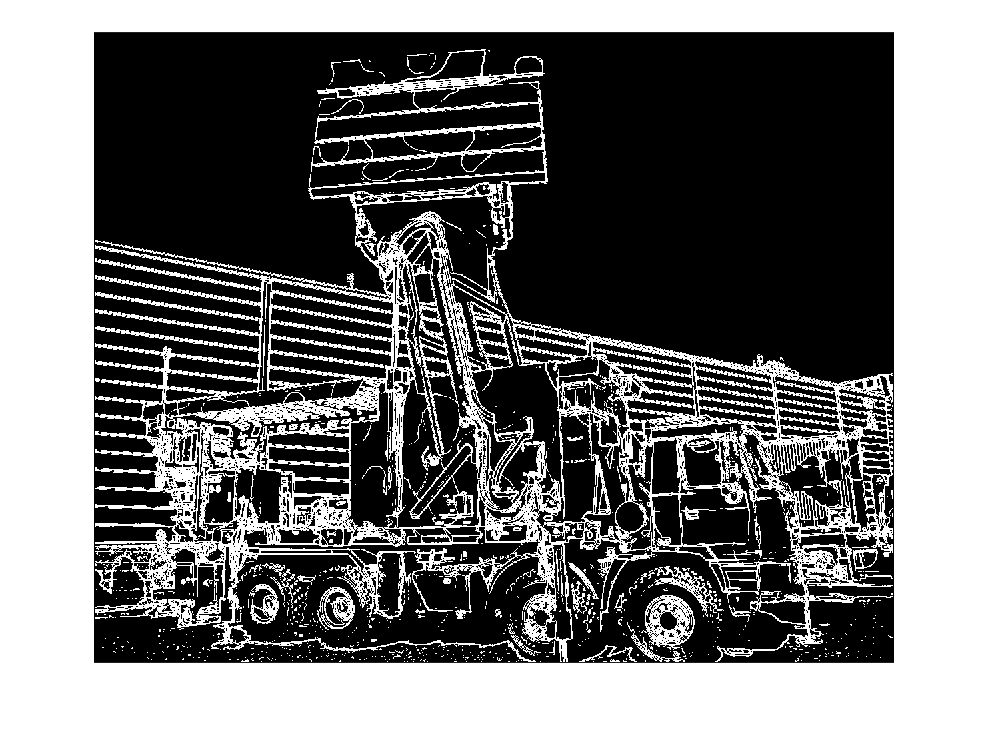


%Progowanie t z zakresu [0;255]. Jeśli t < 0 - bez progowania
t = 20;
[sobel_img, beforeThresh] = sobel_detector(image, t);


imshow(sobel_img);

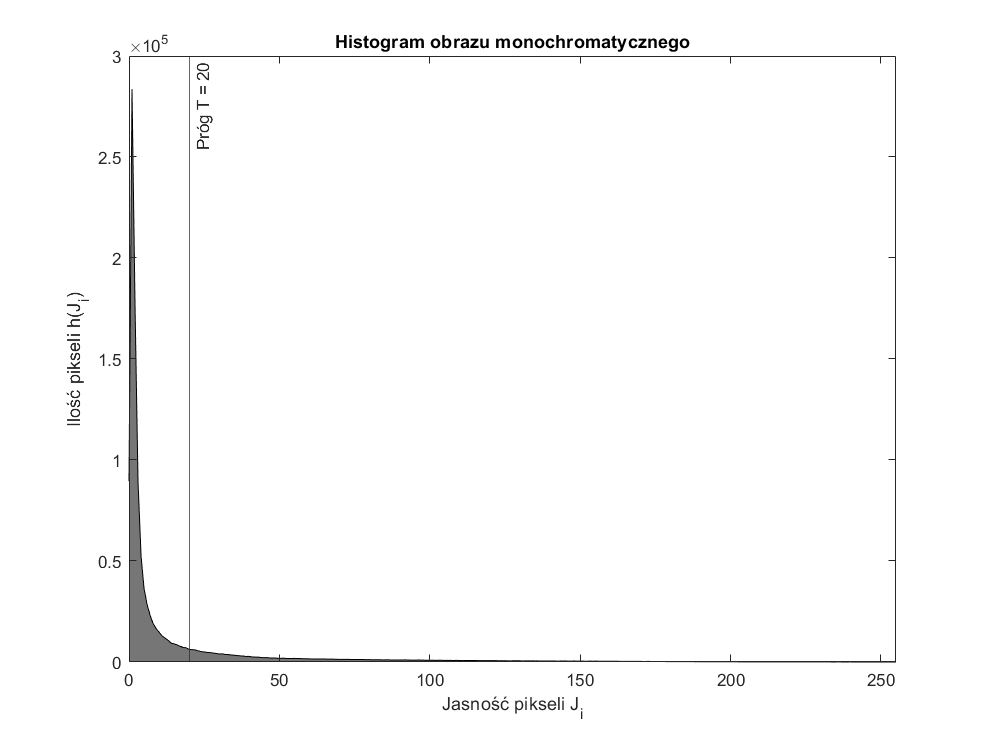

showhistogram(beforeThresh, t);